# CAPÍTULO 07 - DESPLAZAMIENTOS Y ESFUERZOS EN SISTEMAS DE BARRAS

Introduce una estructura espacial para obtener su deformada y las seis componentes de esfuerzo. También puedes conservar el modelo plano o evaluar un resorte.

Dimensión: modelo espacial completo de barras rectas, con modos adicionales plano y resorte. Puedes comprobar la geometría 3D y leer cada esfuerzo por separado.

Modifica los datos y pulsa Run. Las funciones de cálculo están en esta misma carpeta. Abre INICIAR_CURSO.m y ejecútalo una vez al iniciar MATLAB.

## 1. Datos / Input data

Unidades de entrada: m, N, Pa, rad y s, salvo que se indique otra unidad. Los valores iniciales son editables y no seleccionan un ejercicio concreto.

assert(exist('rm_lineal','file')==2, 'Ejecuta INICIAR_CURSO.m una vez antes de abrir los capitulos.');

modo="espacial", "plano" o "resorte". En espacial, nodos tiene columnas [X Y Z]; cargas es [nodo FX FY FZ MX MY MZ] y apoyos es [nodo uX uY uZ giroX giroY giroZ]. NaN deja libre una componente. Fuerzas y momentos siguen ejes globales; los momentos son vectores según la regla de la mano derecha. Para una carga interior añade un nodo en su posición y divide la barra mediante los datos.

modo="espacial";
nodos=[0 0 0; 0 1 0; 2 1 0; 2 0 0];
barras=[1 2; 2 3; 3 4];
E=210e9; G=80e9; F=.005; Iy=8e-6; Iz=8e-6; J=16e-6;
cargas=[3 0 0 -1000 0 0 0];
apoyos=[1 0 0 0 0 0 0; 4 0 0 0 0 0 0];
qGlobal=[0 0 0 0 0 0; 0 0 0 0 -1000 -1000; 0 0 0 0 0 0];
qLocal=zeros(size(barras,1),8);
referenciaY=zeros(size(barras,1),3);
tipoBarra="viga";
liberaciones=zeros(0,3);
deformacionLibre=0; curvaturaLibre=[0 0]; giroLibre=0;
consulta=[3 3];
vistaEpiuras="ambas"; mostrarCeros=false;

qGlobal tiene una fila por barra: [qX_inicio qX_final qY_inicio qY_final qZ_inicio qZ_final], en N/m. qLocal permite añadir [qx0 qx1 qy0 qy1 qz0 qz1 mx0 mx1]; mx es un par repartido en N·m/m. Se suman ambas tablas. referenciaY indica la dirección transversal de la sección; [0 0 0] elige una base automáticamente. Iy e Iz deben corresponder a ejes principales de la sección, con Iyz=0. Usa los ejes calculados en el capítulo 3 y fija referenciaY en esa dirección; no introduzcas inercias de ejes no principales sin transformarlas.

tipoBarra admite "viga", "axial" o un valor por barra; axial transmite N y no momentos. liberaciones usa [barra extremo componenteLocal], con extremo 1/2 y componente 4=torsión, 5=giro y, 6=giro z. Los demás grados mantienen continuidad. consulta=[nodo componente] emplea 1..3 para desplazamientos globales y 4..6 para giros. Para usar el modelo plano rellena la siguiente tabla y selecciona modo="plano".

nodosPlano=[0 0;0 2;3 2;3 0];
barrasPlano=[1 2;2 3;3 4]; Iplano=8e-6;
cargasPlano=[3 5000 -10000 0];
apoyosPlano=[1 0 0 0;4 0 0 0];
qPlano=[0 0 0 0;0 0 -1000 -1000;0 0 0 0];
liberacionesPlano=zeros(0,2); consultaPlano=[3 2];
deformacionLibrePlano=0;curvaturaLibrePlano=0;
Dresorte=.10; dalambre=.008; vueltas=8; Gresorte=80e9;
Eresorte=210e9; fuerzaResorte=200; parResorte=2;

## 2. Equilibrio y trabajo virtual


$$\Delta=\sum_i\int\left(\frac{N_i n_i}{E_iF_i}+\frac{M_{yi}m_{yi}}{E_iI_{yi}}+\frac{M_{zi}m_{zi}}{E_iI_{zi}}+\frac{M_{xi}m_{xi}}{G_iJ_i}\right)ds$$


Las letras minúsculas corresponden a una carga o par unitario en la dirección de consulta. El cálculo añade las deformaciones libres y el trabajo de apoyos desplazados. La integración de los polinomios es analítica; el dibujo se muestrea. Las reacciones usan los ejes globales y las epiuras usan los locales de cada barra.


$$\mathbf{u}_{local}=\mathbf{T}\mathbf{u}_{global},\qquad \mathbf{K}_{global}=\sum_i\mathbf{T}_i^T\mathbf{k}_i\mathbf{T}_i,\qquad \mathbf{K}\mathbf{u}=\mathbf{f}+\mathbf{R}$$


if modo=="espacial"
    datos=struct('nodos',nodos,'barras',barras,'E',E,'G',G,'F',F,'Iy',Iy,'Iz',Iz,'J',J, ...
        'cargas',cargas,'apoyos',apoyos,'qGlobal',qGlobal,'qLocal',qLocal, ...
        'referenciaY',referenciaY,'tipo',tipoBarra,'liberaciones',liberaciones, ...
        'deformacionLibre',deformacionLibre,'curvaturaLibre',curvaturaLibre,'giroLibre',giroLibre);
    resultado=rm_mohr3d(datos,consulta);
    disp(table(resultado.deltaNodal,resultado.deltaMohr, ...
        'VariableNames',{'Respuesta_nodal','Integral_Mohr'}));
    disp('Desplazamientos [m] y giros [rad], columnas X Y Z giroX giroY giroZ:'); disp(resultado.u);
    disp('Reacciones [N] y momentos [N m], columnas FX FY FZ MX MY MZ:'); disp(resultado.R);
elseif modo=="plano"
    datos=struct('nodos',nodosPlano,'barras',barrasPlano,'E',E,'F',F,'I',Iplano, ...
        'cargas',cargasPlano,'apoyos',apoyosPlano,'q',qPlano,'liberaciones',liberacionesPlano, ...
        'deformacionLibre',deformacionLibrePlano,'curvaturaLibre',curvaturaLibrePlano);
    resultado=rm_mohr_plano(datos,consultaPlano);disp(resultado.u);disp(resultado.R);
    disp(table(resultado.deltaNodal,resultado.deltaMohr, ...
        'VariableNames',{'Respuesta_nodal','Integral_Mohr'}));
else
    assert(modo=="resorte" && all([Dresorte dalambre vueltas Gresorte Eresorte]>0),'Datos invalidos.');
    flexibilidad=8*Dresorte^3*vueltas/(Gresorte*dalambre^4);
    flexibilidadAngular=64*Dresorte*vueltas/(Eresorte*dalambre^4);
    deltaResorte=fuerzaResorte*flexibilidad; giroResorte=parResorte*flexibilidadAngular;
    resultado=struct('delta',deltaResorte,'giro',giroResorte);
    disp(resultado);
end

    Respuesta_nodal    Integral_Mohr
    _______________    _____________

      -0.00035658       -0.00035658 



Desplazamientos [m] y giros [rad], columnas X Y Z giroX giroY giroZ:
   1.0e-03 *

         0         0         0         0         0         0
         0         0   -0.2387   -0.3721    0.1596         0
         0         0   -0.3566   -0.5207   -0.0656         0
         0         0         0         0         0         0



Reacciones [N] y momentos [N m], columnas FX FY FZ MX MY MZ:
   1.0e+03 *

         0         0    1.0602    1.1553   -0.2043         0
         0         0    0.0000         0   -0.0000         0
         0         0   -0.0000         0         0         0
         0         0    1.9398    1.8447    0.0840         0



Una rótula puede dejar un giro sin rigidez. En ese caso su valor absoluto se toma como referencia numérica, sin añadir un apoyo físico ni momentos espurios. Una traslación sin rigidez o un par aplicado en un giro liberado se rechaza como mecanismo.

## 3. Geometría 3D y epiuras automáticas

vistaEpiuras="locales", "espaciales", "ambas" o "geometria". La vista 3D permite comprobar orientación y deformada. Las epiuras locales conservan el formato vertical y sus unidades; las espaciales se dibujan sobre las barras con separaciones visuales proporcionales al esfuerzo. mostrarCeros=false omite componentes numéricamente nulas. Las flechas de fuerzas son azules; los vectores de momentos son morados. No están a escala de las deformaciones.

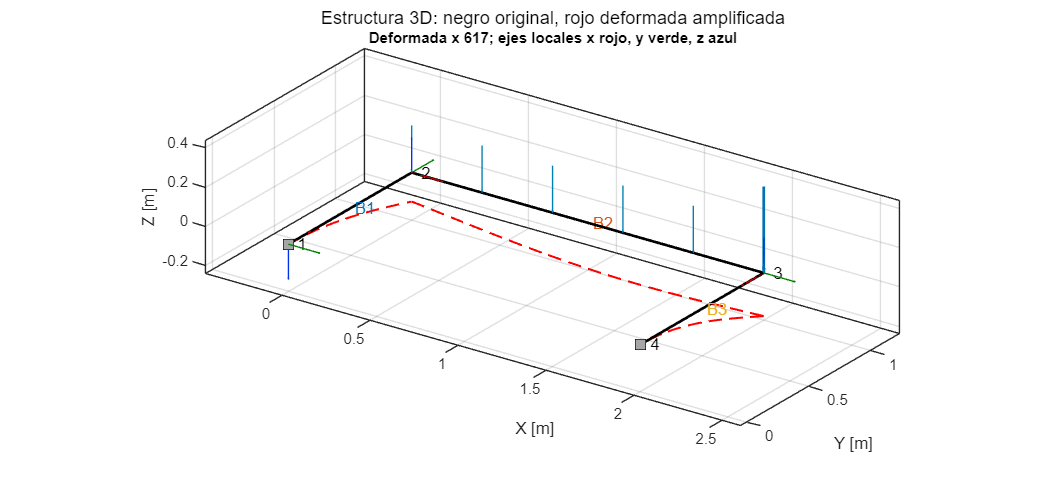

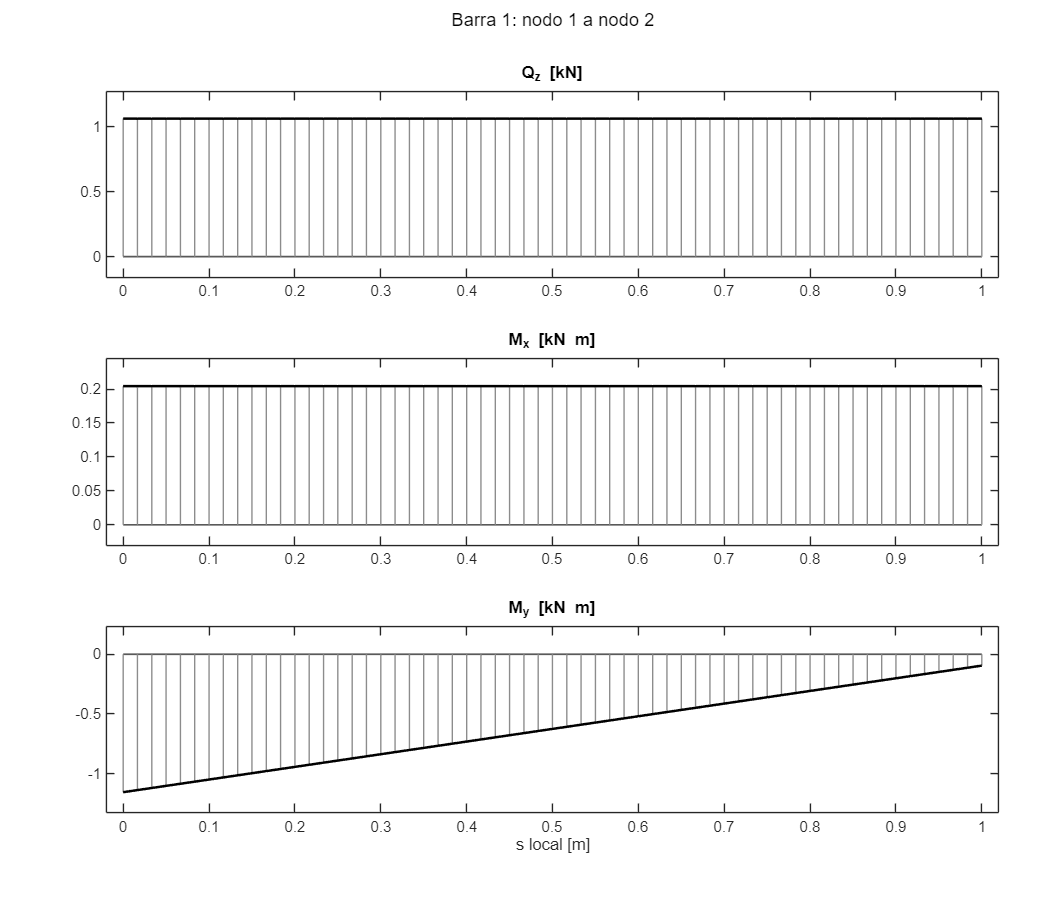

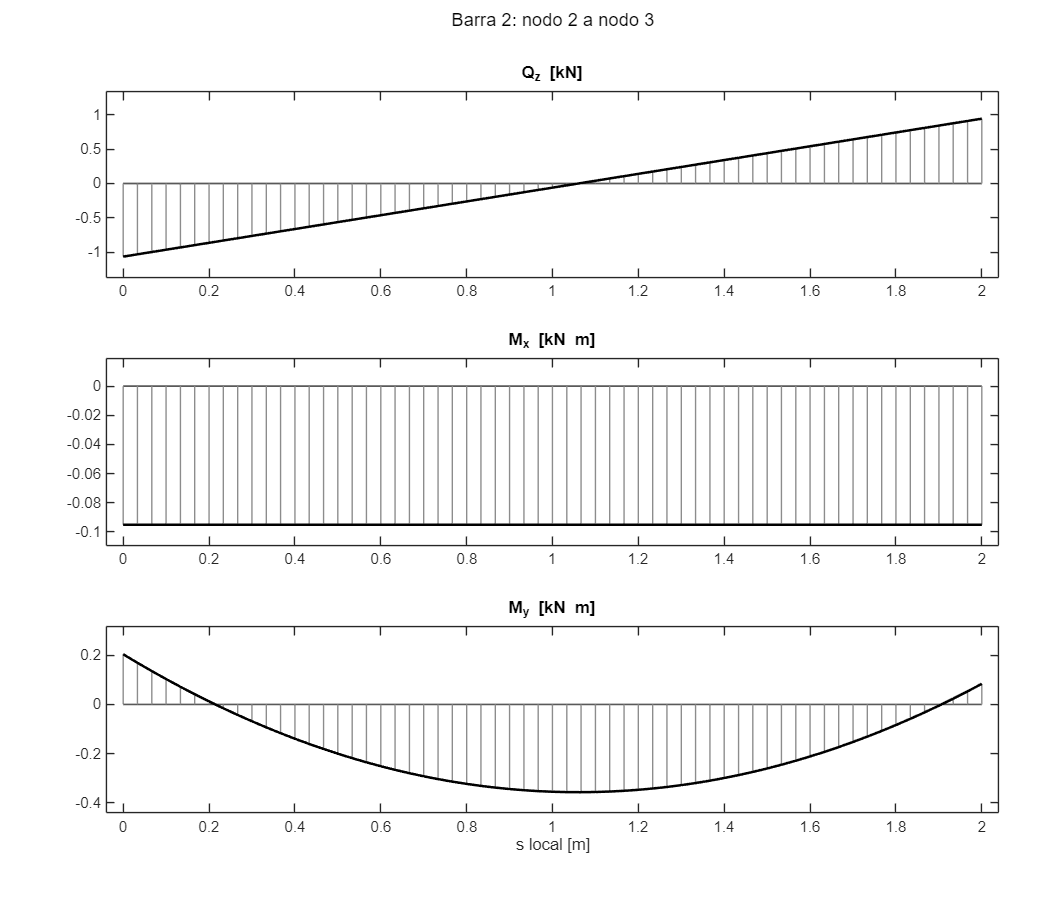

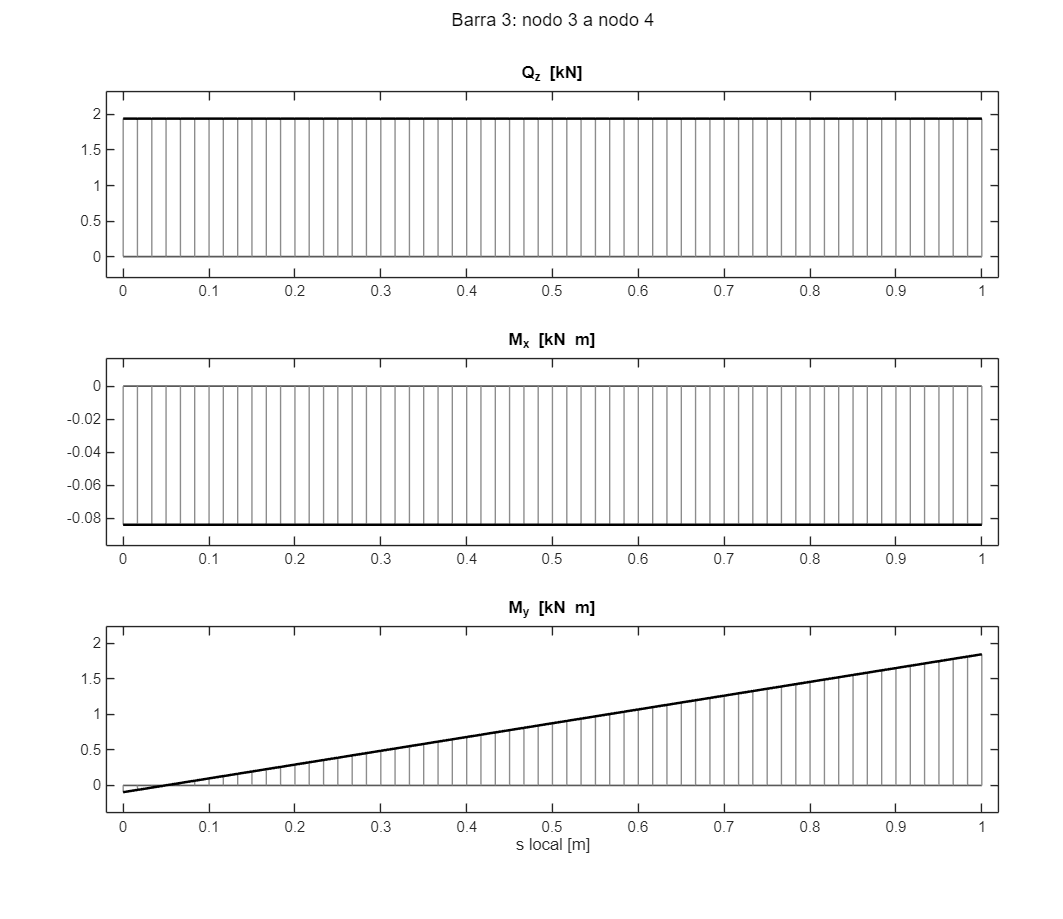

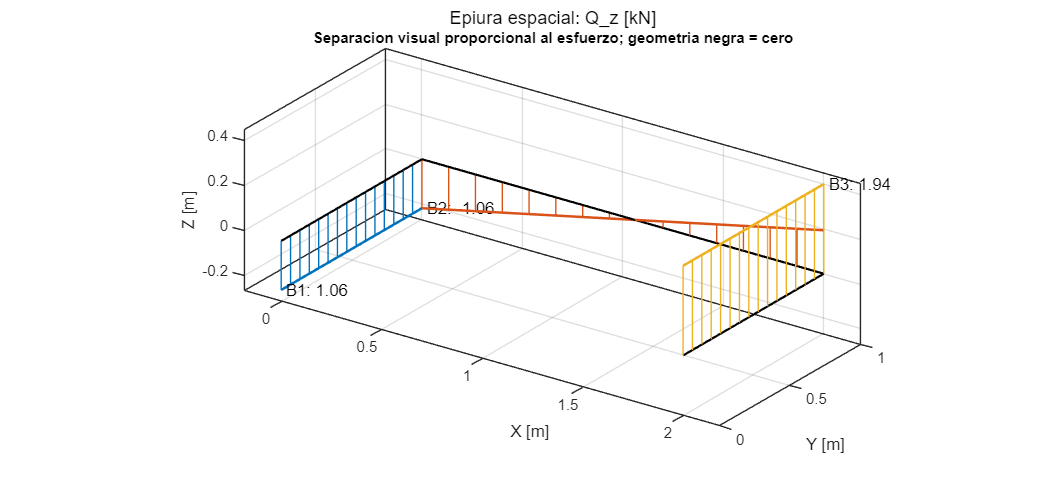

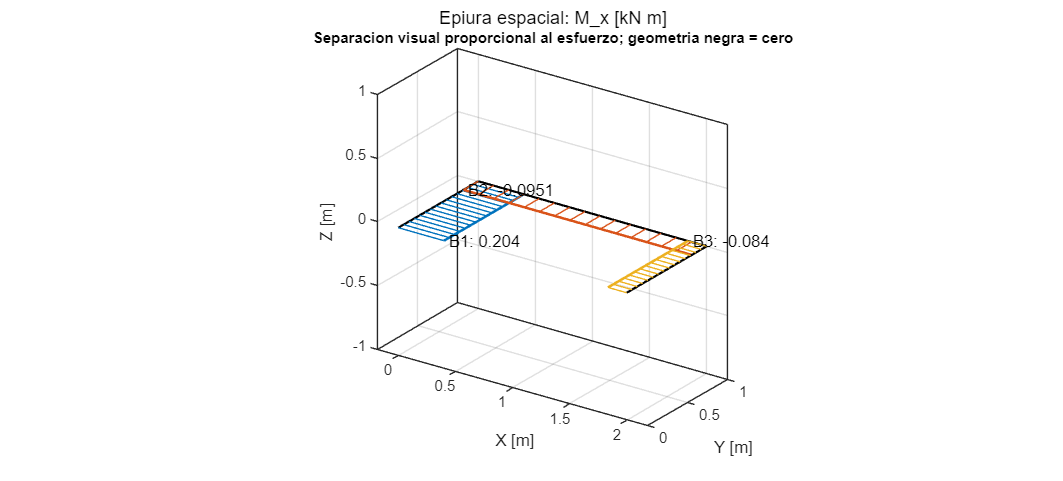

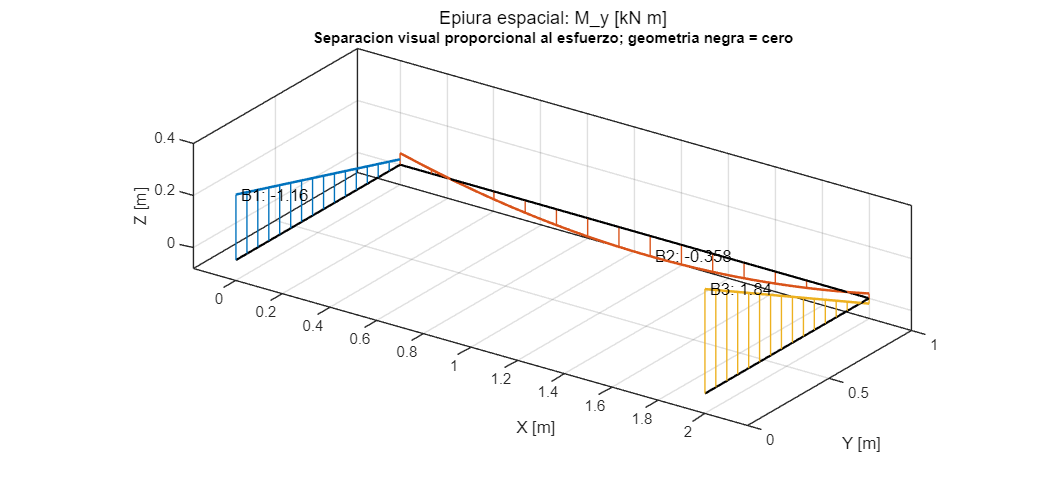

if modo=="espacial"
    figuras=rm_graficar_marco3d(resultado,vistaEpiuras,mostrarCeros);
elseif modo=="plano"
    [figura,ejes]=rm_figura(1,'Marco plano: numeracion'); hold(ejes(1),'on');
    for i=1:size(barrasPlano,1)
        xy=nodosPlano(barrasPlano(i,:),:);plot(ejes(1),xy(:,1),xy(:,2),'k-o');
        text(ejes(1),mean(xy(:,1)),mean(xy(:,2)),sprintf(' B%d',i));
    end
    axis(ejes(1),'equal');
    for i=1:numel(resultado.campos)
        a=resultado.campos{i};s=linspace(0,a.L,101);
        [figura,ejes]=rm_figura(3,sprintf('Barra plana %d',i));
        rm_curva(ejes(1),s,polyval(a.N,s)/1000,'N [kN]');
        rm_curva(ejes(2),s,polyval(a.V,s)/1000,'V [kN]');
        rm_curva(ejes(3),s,polyval(a.M,s)/1000,'M [kN m]');xlabel(ejes(3),'s [m]');
    end
else
    [figura,ejes]=rm_figura(2,'Resorte: respuesta lineal');
    pp=linspace(0,max(1,abs(fuerzaResorte)),101);
    rm_curva(ejes(1),pp,pp*flexibilidad*1000,'\delta [mm]',false);xlabel(ejes(1),'P [N]');
    mm=linspace(0,max(1,abs(parResorte)),101);
    rm_curva(ejes(2),mm,mm*flexibilidadAngular*180/pi,'\phi [grados]',false);xlabel(ejes(2),'M [N m]');
end

## Funciones utilizadas

rm_marco3d: resuelve barras en el espacio. Aquí combina axial, dos flexiones y torsión con seis grados de libertad por nodo.

rm_mohr3d: aplica una carga unitaria y trabajo virtual. Aquí contrasta la componente que has elegido en consulta.

rm_graficar_marco3d: crea geometría y diagramas espaciales/locales. Aquí adapta automáticamente las figuras a las barras y a los esfuerzos no nulos.

cross: calcula un producto vectorial. Aquí la rutina construye un triedro local de mano derecha.

polyint y conv: integran polinomios y multiplican sus coeficientes. Aquí permiten integrar energía y trabajo virtual sin error de muestreo.

disp muestra valores; aquí presenta las tablas y conclusiones. assert comprueba una condición; aquí rechaza datos incompatibles. table reúne columnas con nombre; aquí permite leer resultados con unidades. rm_figura prepara ejes verticales; aquí reserva espacio para títulos y unidades. rm_curva dibuja una magnitud; aquí diferencia el cero gris de la curva negra y el rayado.

GUIA_MATLAB.md, en esta misma carpeta, explica las operaciones básicas en general y con un ejemplo de su uso en estos capítulos.

## Alcance y conexiones

Barras rectas prismáticas elásticas: marcos 3D con seis grados de libertad por nodo, barras axiales y marcos 2D. Flexión Euler-Bernoulli y torsión de Saint-Venant; no incluye alabeo restringido, deformación por cortante, grandes giros ni pandeo. Las curvas discretizadas con barras rectas requieren convergencia de malla y curvatura moderada respecto al tamaño de sección.

Conexión con lo anterior: Combina EF del capítulo 1, GJ del 4 y las dos rigideces de flexión del 5. El capítulo 9 utiliza los esfuerzos espaciales de estas mismas rutinas.

Cambiar datos no requiere editar las ecuaciones. Una geometría, ley de material o condición fuera del alcance indicado requiere ampliar el modelo. Un cálculo que satisface equilibrio no demuestra por sí solo resistencia o estabilidad suficiente.

disp('Capitulo 07: calculo completado.');

Capitulo 07: calculo completado.
